Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)
load('saved_rawDataName.mat')
load(OptResults1)

Tau = 0.08; % initial value of time constants, based on Franken et al. 1992
scalePWP = 0.0848; % set PWP to have no effect
circadianAmp = 0.0311; % set circadian process to have no effect
circadianPhase = -2.1236; % set circadian process to have no phase
sizePWP = [0,0.1,5]; % Possible Values. [X,Y,Z] translated to X:Y:Z
shiftPWP = [-5,0.1,5];  % Possible Values. [X,Y,Z] translated to X:Y:Z

rawData_all = ([Temperature_path,'rawData_all_0920.mat'])

rawData_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/rawData_all_0920.mat'

OptResults_all =([Temperature_path,'OptResults_all_0922.mat'])

OptResults_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/OptResults_all_0922.mat'

OptResults_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/OptResults_all_0920.mat'

edit example2_Optimization.m
% replace the initial factors use those above

c=parcluster

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-iMac
                NumWorkers: 25
                NumThreads: 4

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

j5=batch(@example2_Optimization,0,{rawData_all, 1, OptResults_all})

j5 = 

 Job

    Properties: 

                   ID: 61
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 22-Sep-2022 23:52:22
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

load(OptResults_all)

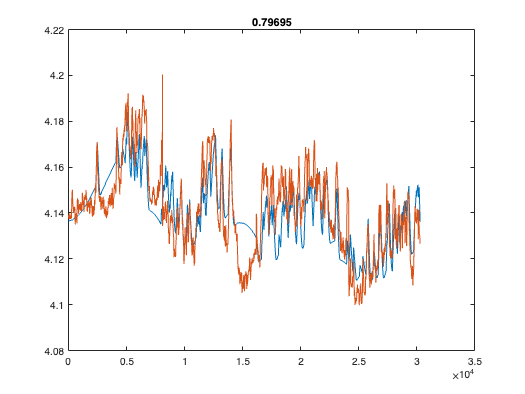

figure
plot(simulatedT)
hold on
plot(rawT)
title(num2str(correlation))